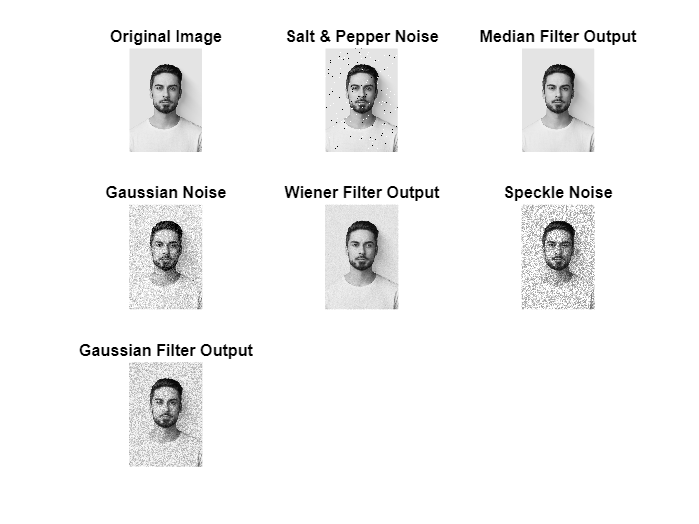

%% Noise Addition & Removal in Images - MATLAB Project
clc;
clear;
close all;

%% Step 1: Read and prepare the image
img = imread('D:\sreekar\NOISE ADDITION AND CANCELATION USING MATLAB\IMAGE.png'); % Replace with your own image if needed
img_gray = rgb2gray(img);    % Convert to grayscale

%% Step 2: Add different types of noise
noisy_sp = imnoise(img_gray, 'salt & pepper', 0.02); % Salt & pepper noise
noisy_gauss = imnoise(img_gray, 'gaussian', 0, 0.01); % Gaussian noise
noisy_speckle = imnoise(img_gray, 'speckle', 0.04);   % Speckle noise

%% Step 3: Apply noise removal filters
% For Salt & Pepper -> Median Filter
denoised_median = medfilt2(noisy_sp, [3 3]);

% For Gaussian -> Wiener Filter
denoised_wiener = wiener2(noisy_gauss, [5 5]);

% For Speckle -> Gaussian Smoothing Filter
h = fspecial('gaussian', [3 3], 0.5);
denoised_gauss = imfilter(noisy_speckle, h);

%% Step 4: Display everything in one figure
figure('Name', 'Noise Addition & Removal', 'NumberTitle', 'off');

subplot(3,3,1), imshow(img_gray), title('Original Image');

subplot(3,3,2), imshow(noisy_sp), title('Salt & Pepper Noise');
subplot(3,3,3), imshow(denoised_median), title('Median Filter Output');

subplot(3,3,4), imshow(noisy_gauss), title('Gaussian Noise');
subplot(3,3,5), imshow(denoised_wiener), title('Wiener Filter Output');

subplot(3,3,6), imshow(noisy_speckle), title('Speckle Noise');
subplot(3,3,7), imshow(denoised_gauss), title('Gaussian Filter Output');


%% Step 5: Performance Comparison (MSE & PSNR)
% Salt & Pepper
mse_median = immse(img_gray, denoised_median);
psnr_median = psnr(denoised_median, img_gray);

% Gaussian
mse_wiener = immse(img_gray, denoised_wiener);
psnr_wiener = psnr(denoised_wiener, img_gray);

% Speckle
mse_gauss = immse(img_gray, denoised_gauss);
psnr_gauss = psnr(denoised_gauss, img_gray);
%% mean square error and peak signal to noise ratio
fprintf('--- Performance Results ---\n');

--- Performance Results ---


fprintf('Median Filter (Salt & Pepper): MSE = %.4f, PSNR = %.2f dB\n', mse_median, psnr_median);

Median Filter (Salt & Pepper): MSE = 4.7003, PSNR = 41.41 dB


fprintf('Wiener Filter (Gaussian):      MSE = %.4f, PSNR = %.2f dB\n', mse_wiener, psnr_wiener);

Wiener Filter (Gaussian):      MSE = 48.0772, PSNR = 31.31 dB


fprintf('Gaussian Filter (Speckle):     MSE = %.4f, PSNR = %.2f dB\n', mse_gauss, psnr_gauss);

Gaussian Filter (Speckle):     MSE = 530.2662, PSNR = 20.89 dB
